# Basics of Scripting

## Section 1: Navigating Matlab

By default, Matlab is broken into five separate boxes:

**Command window: **Running basic commands, displaying output etc. 

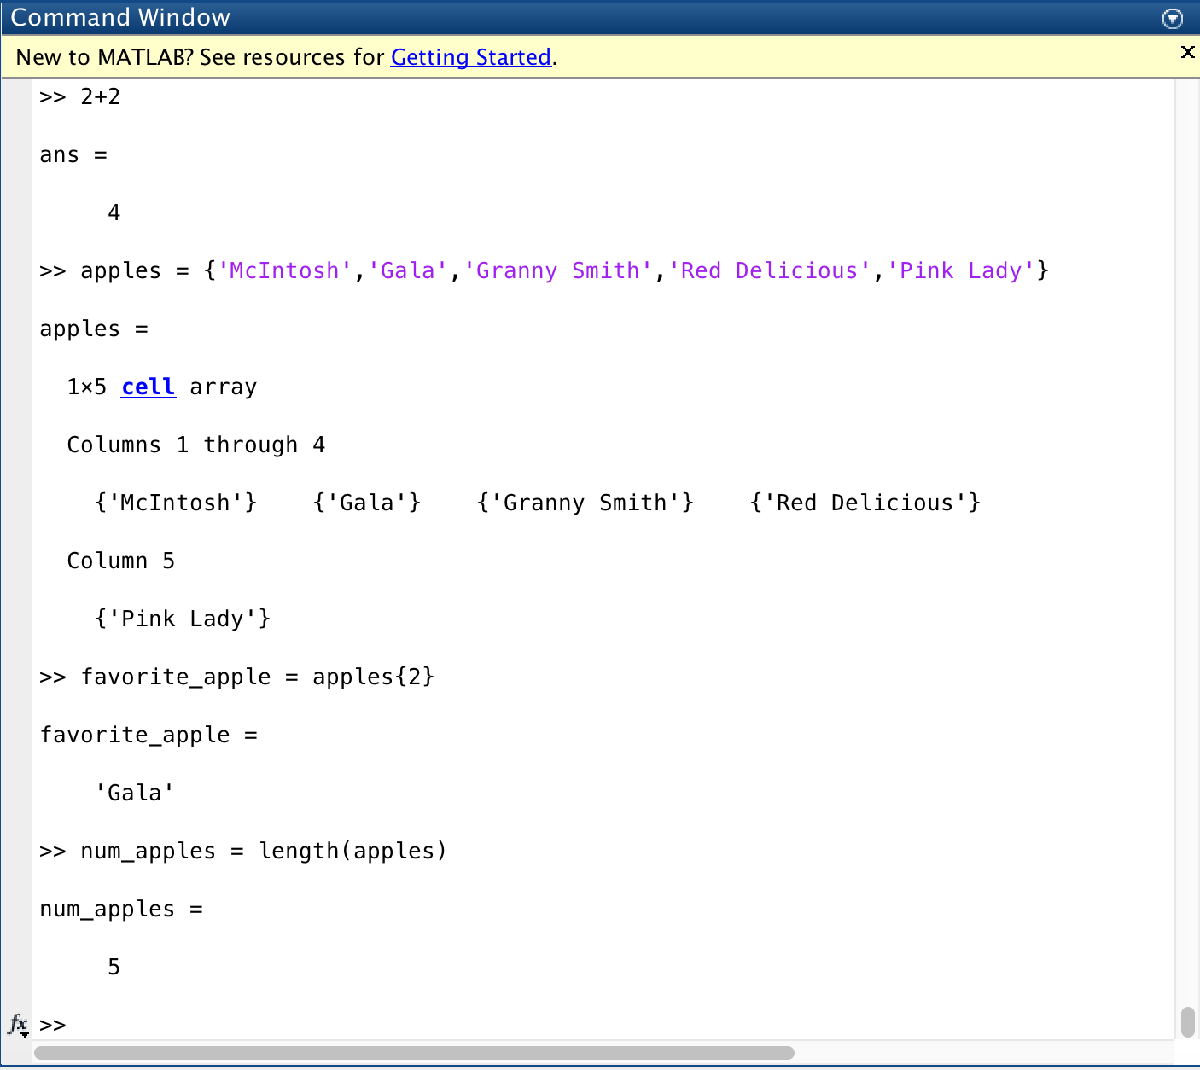

**Workspace: **View variable names, values, types, sizes.

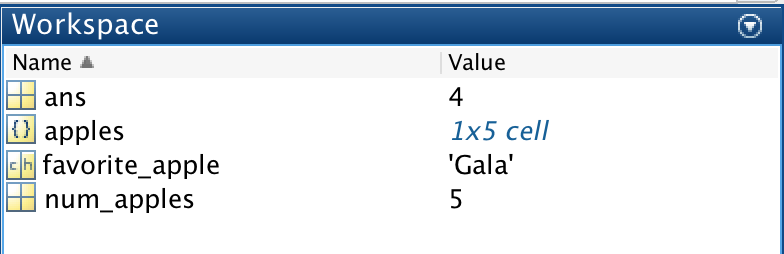

**Editor: **Writing, debugging scripts.

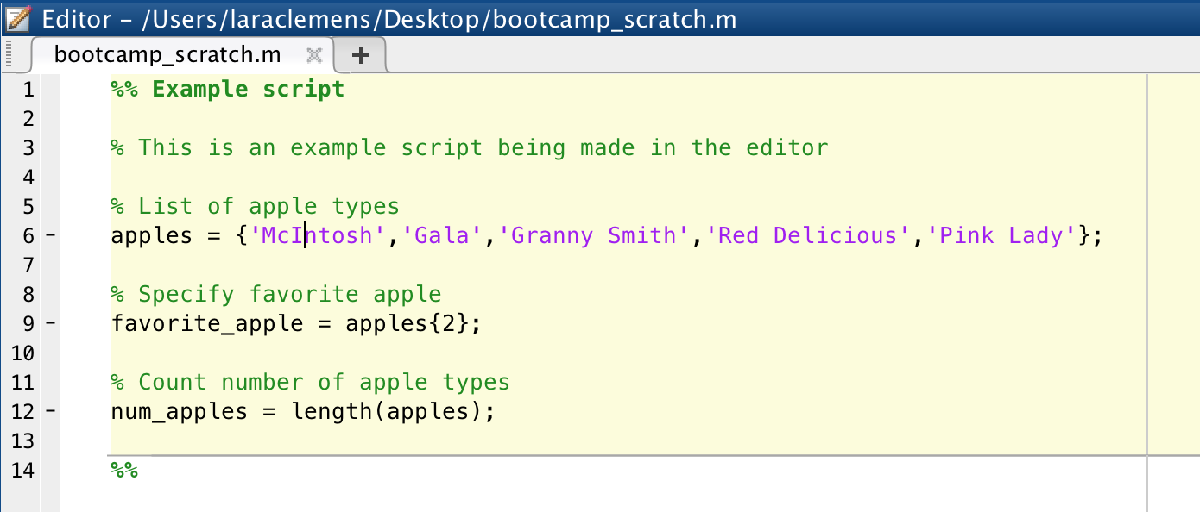

**Current folder: **Folder navigation system. 

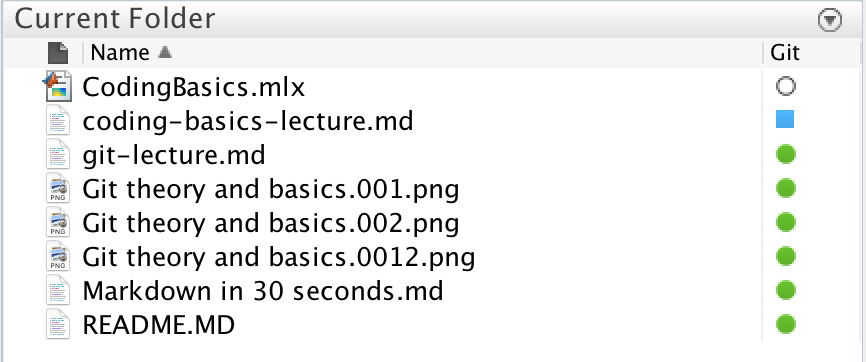

**Details: **View details of script selected in Current Folder window, including section headers.

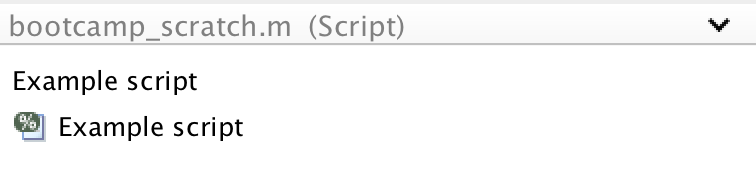

Each of these can be resized, dragged to a new position, or moved to it's own window (undocked). 

You can choose what works for you.

## Section 2: Variables

**Subsection 2.1: Math in the command window**

Working in the command window, try the following:


$$123 + 987$$



$$551/17$$



$$4-6/2$$


(551/17)+sin(551/17)/4 - (551/17)^(-2/3)

**Subsection 2.2: Variables**

Often calculations are simpler if you can store values somewhere. This let's you use the same number multiple times, store values for future use, creates more readable expressions, change a number in a single location rather than everywhere it's used etc

Matlab stores variables with '=':

x = 5

time = 10

n_people = 7.7e9

Variables names always go to the left of the expression:

vel = 4 <- WORKS

4 = vel <- DOES NOT WORK

**Subsection 2.3: Naming variables**

There are some hard rules and some soft rules regarding variable names:

- variable names must begin with a letter (not a number,symbol)

- cannot contain spaces (can use underscores, camel case)

- Note: uppercase and lowercase letters are distinct

Variable names are something you should think a lot about. Some rules of thumb:

- helps to be descriptive (e.g. num_people vs n)

- pick a convention and stick with it (e.g. always starting with lowercase, using all capitals for variables that shouldn't change, etc)

- avoid names of Matlab functions (e.g. sqrt, sin)

Some names are protected by Matlab. These will turn blue before you try to assign it:

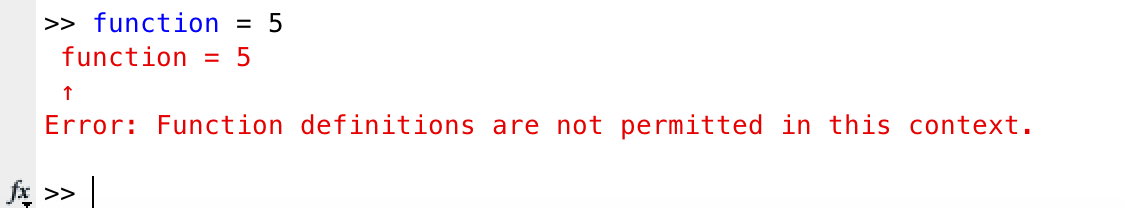

**Subsection 2.4: Clearing variables**

Sometimes it is helpful to clear a variable.

To clear just variables:

Clears all variables: 

clearvars

Clears only those specified: 

clearvars variable1 variable2

To clear more than just variables (see Matlab documentation for [clear](https://www.mathworks.com/help/matlab/ref/clear.html)):

clear (or clear all)

clear variable1 variable2

## Section 3: Scripts, Functions

**Subsection 3.1: Scripts (.m)**

Scripts can be used to save work, run lots of commands at once, debug, create functions, etc.

Scripts are the default file for writing code in Matlab. Scripts simply run what is written. 

All variables are *global, *and are not cleared unless specified by user. 

**Subsection 3.1: Functions (.m)**

Functions can take an input and return an output. Used if a section of code will be used many times. 

All variables defined in the function are *local* and cannot be seen by an encapsulating script. This is generally viewed as safer than the global variables of scripts - they won't get overwritten, used unexpectedly etc.

**Subsection 3.2: Live scripts (.mlx)**

Live scripts (like this one) can be used to include plain text, latex equations, and images along with the code. It will also display output in-line or to the side when each section is run.

This is particularly useful for documentation and teaching. 

Drawbacks of live scripts:

- They are slower than plain scripts.

- Github, git reads the live script as a binary file - it will not show you line-by-line changes.

- Still new - older Matlab versions limit capabilities, making sharing with collaborators harder.

## Section 4: If Statements

If statements are a way to do something conditionally. Accepts logical '1' (true) or '0' (false). If/Else statements follow the structure "If this, then do this. Otherwise, do this other thing." 

% If hungry, feed the cookie monster
hungryTF = 1;
if(hungryTF)
    disp('Fed the cookie monster a cookie!');
    hungryTF = 0;
end

Fed the cookie monster a cookie!



% Display if x is divisible by 9
x = 51;
if(mod(x,9) ~= 0)
    disp('x is not divisible by 9');
else
    disp('x is divisible by 9');
end

x is not divisible by 9


There are also ways to address many possible conditions. If/ElseIf/Else statements and Switch statements are good for this. If/ElseIf works for inequalities and other such operators, whereas Switch works on specific values (numbers, strings etc).

% produce random number uniformly distributed from 0 to 1
randUnif = rand;
% initialize bins
count75 = 0;
count50 = 0;
count25 = 0;
count00 = 0;

% decide which bin randUnif should go in
if(randUnif >= 0.75)
    count75 = count75+1;
elseif(randUnif >= 0.5)
    count50 = count50+1;
elseif(randUnif >= 0.25)
    count25 = count25+1;
else
    count00 = count00+1;
end

% Create switch based on which apple is requested
requestedApple = 'Cortland'

requestedApple = 'Cortland'


switch requestedApple
    case 'Honeycrisp'
        disp('These are expensive!');
        
    case {'Gala','Cortland','Braeburn','Empire'}
        disp('Good Choice!');
        
    case 'Red Delicious'
        disp('You heathen!');
        
    case 'Granny Smith'
        disp('Buy some caramel too!');
        
    otherwise
        disp('Out of stock - pick something else!');
        
end

Good Choice!


## Section 5: For Loops

For loops are good for doing the same task over and over again, or for many different values.


% create loop to print numbers 1 through 10
for i = 1:10
    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10




% create loop to sum numbers -5 to 45
x = 0;
for i = -5:45
    x = x+i;
end
disp(x);

        1020



## Section 6: While Loops

While loops are good for tasks that need to be done an unknown number of times. They follow the structure '*While *this is true, do this.'

## Section 7: Vectors, Matrices, Indexing

## Section 8: Plotting

Visualizing data and functions is important for explaining and understanding models, results, and trends. Matlab has a very basic way to plot:

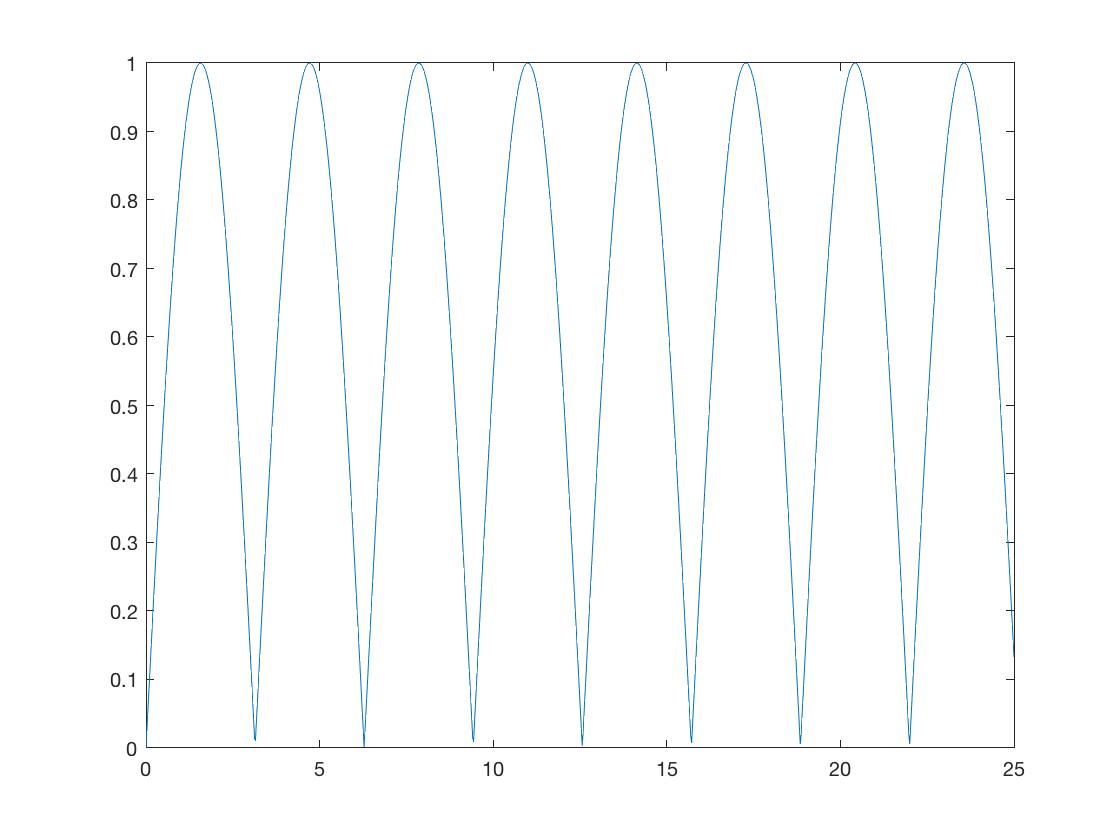

% create some data to plot
x_data = linspace(0,25,1000);
y_data = abs(sin(x_data));

% plot
figure;
plot(x_data,y_data);

How can we make this plot nicer?

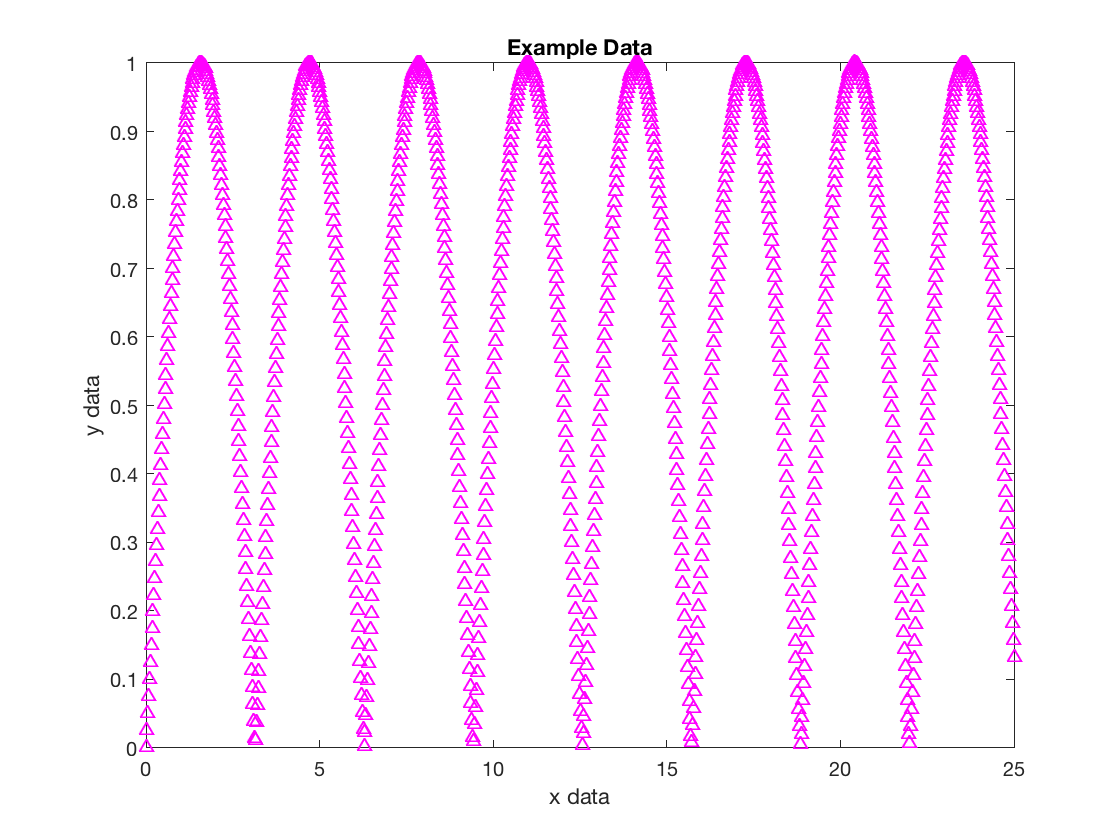

figure('Name','Example data'); 
plot(x_data,y_data,'^m'); % ^ denotes a possible marker style (triangles), m indicates preset color (magenta)
xlabel('x data');
ylabel('y data');
title('Example Data');

What about plotting multiple datasets on the same graph?

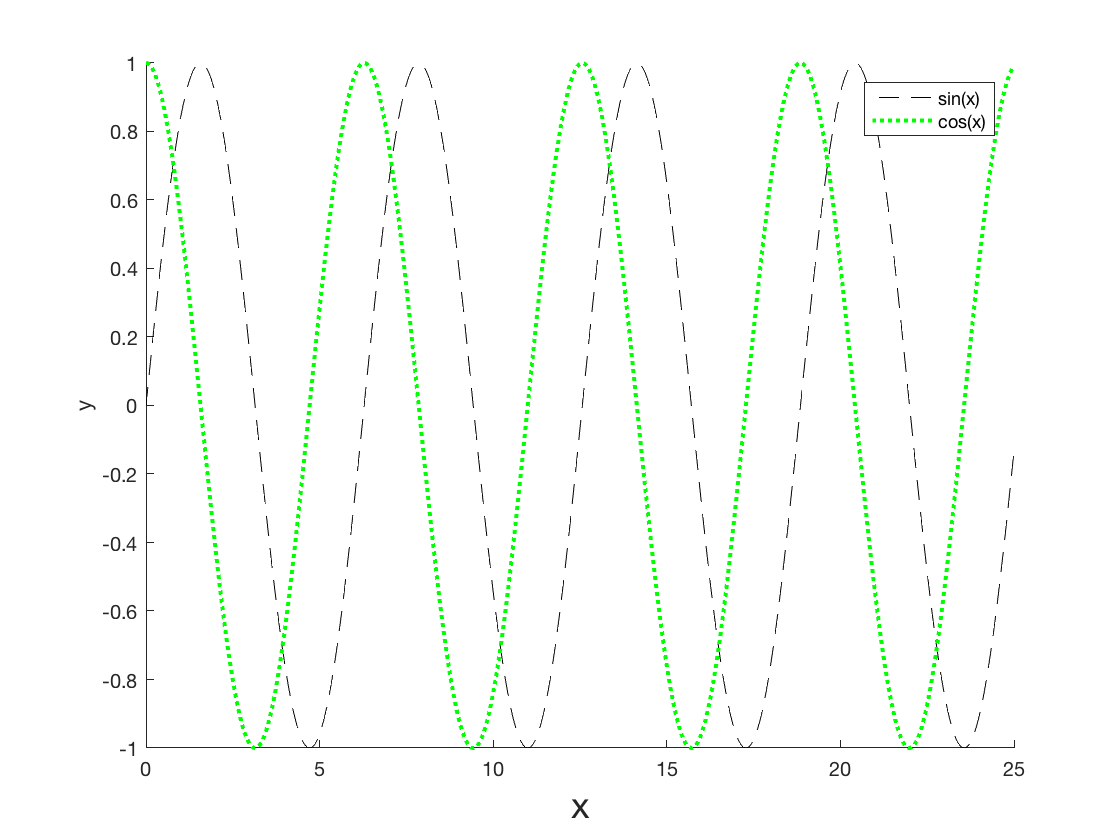

% plot sin(x), cos(x) on same axes
figure('Name','Sin(x) and Cos(x)'); hold on; 
pSin = plot(x_data,sin(x_data),'LineStyle','--','Color','k'); % could equivalently write plot(x_data,sin(x_data),'--k');
pCos = plot(x_data,cos(x_data),':g');
pCos.LineWidth = 2; % could use 'LineWidth',2 in plot() instead
xlabel('x','FontSize',18);
ylabel('y');
legend('sin(x)','cos(x)');

The command '[hold](https://www.mathworks.com/help/matlab/ref/hold.html) on' means any new plots will end up on same figure without overwriting. This will continue until 'hold off' is called, or until a new figure is called.

Assigning a plot to a variable is called a 'plot handle'. You can make many manipulations after the fact if you've saved the plot handle. It's also an alternate way to make property changes without having a very long single line of code. Similarly, you can save figure or axes handles.

Figures in Matlab are infinitely customizable with varying levels of ease.

Some other helpful ways to customize:

- xlim, ylim - set limits for axes

- xtick, ytick - set where axes ticks should occur

- set Position - set position on screen and size of a figure or axes within a figure

- [List of line properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

- [List of axes properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.axis.axes-properties.html)

There are many other [types of plots](https://www.mathworks.com/help/matlab/creating_plots/types-of-matlab-plots.html) that are useful:

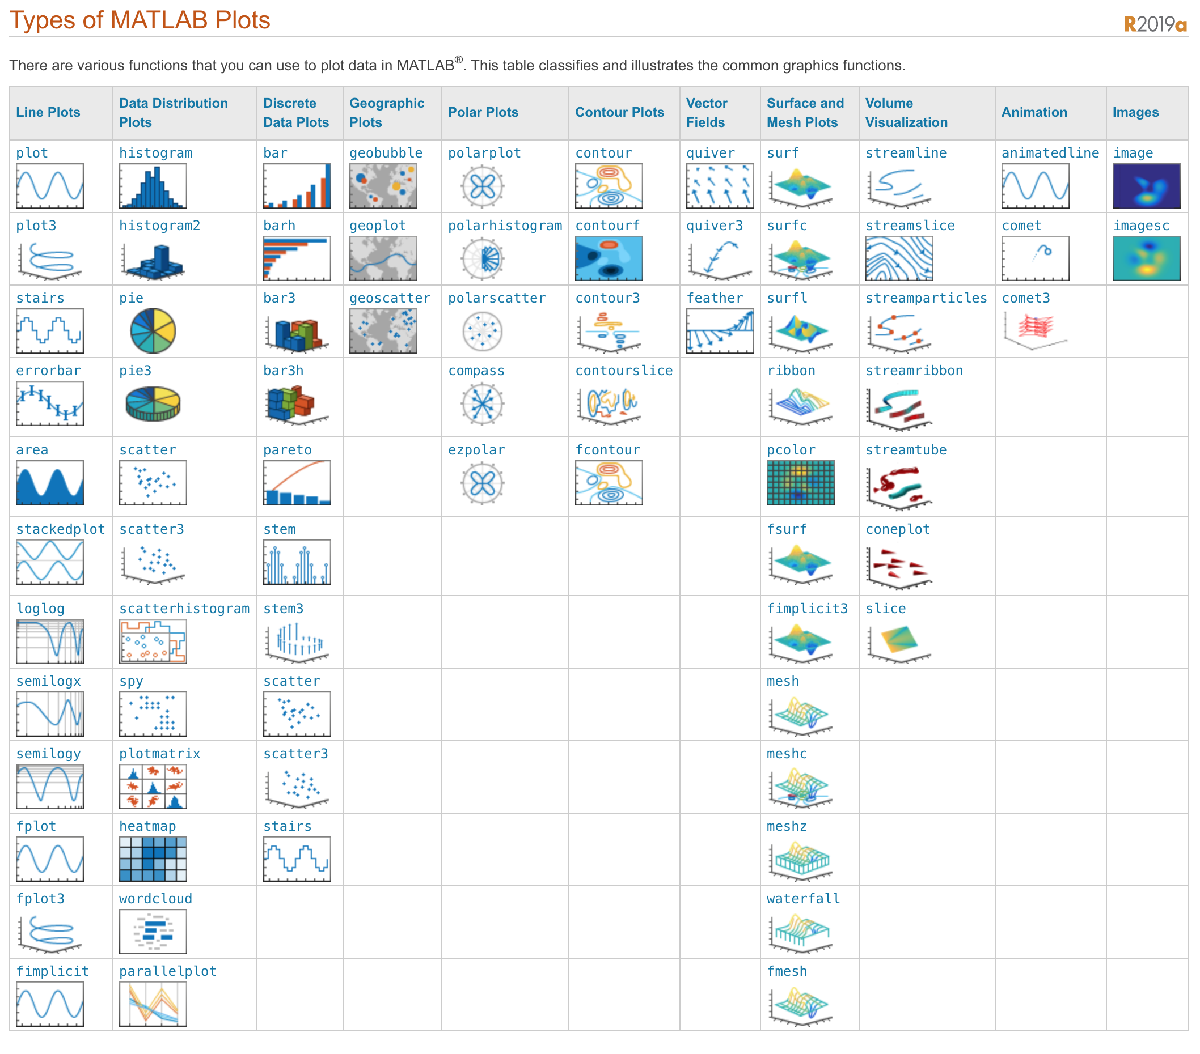

## Section 9: Save, Load

Saving data or figures in matlab is easy. 

For data, it's particularly convenient for scripts that take a long time to run, a way to save progress, or for data you need to use many times in other scripts. 

For figures, it's a nice way to automatically save your figures in a specific format to a specific location.

% saving data

% create some data to save
t_data = linspace(0,24,100);
temperature_data = -8*cos((t_data-3)/4)+70;

% plot data
fig_weather = figure; clf; 
plot(t_data,temperature_data,'-r','DisplayName','temperature');
xlabel('time (hr)');
ylabel('temperature (\circ F)');
title('Typical SoCal Weather Over a Day')


% this saves entire workspace as .mat file
% give a full file path to send the file to a location other than your current directory
% data should not be saved in your git repository
% in general, don't save it to your desktop either - pick a smart place for it
save('~/Desktop/CodingBasics_Example.mat');

% this saves specific variables
save('~/Desktop/SoCalWeather.mat','t_data','temperature_data');



By default, if a .mat file exists with the same name, then saving to it will overwrite the file. If instead, you want to append new variables, or overwrite specific variables, there is an option for that:

% create more data to save
precipitation_data = zeros(size(t_data));

% this appends data
save('~/Desktop/SoCalWeather.mat','precipitation_data','-append');

% plot this data too
figure(fig_weather); hold on;
yyaxis right; % creates second y-axis on the right
plot(t_data,precipitation_data,'ob','DisplayName','precipitation');
ylabel('precipitation (mm)')
legend('Location','southeast');


To save a figure, you need to specify the figure with a figure handle, or 'gcf' (get current figure). It also needs a filepath, and format (fig, epsc, pdf, png etc).

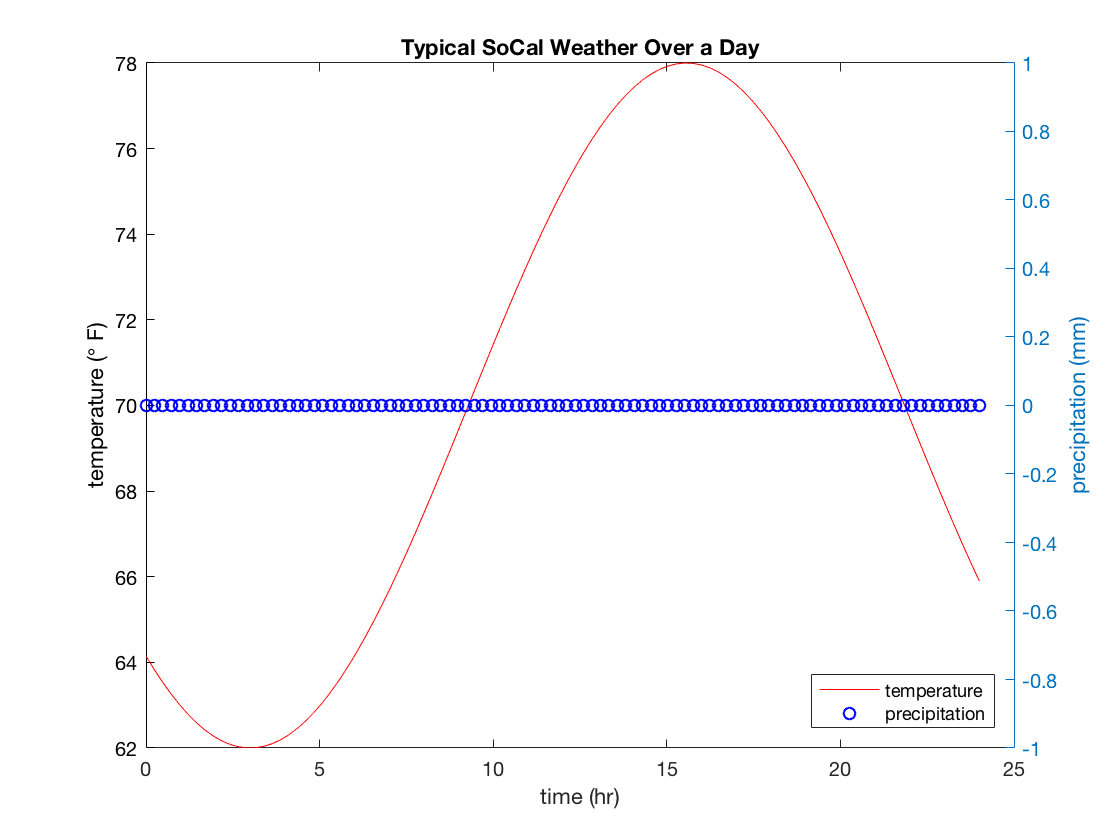

% this saves the figure
saveas(fig_weather,'~/Desktop/SoCalWeather','fig');

Loading data from a .mat file is similar. Either the entire file can be loaded, or just specific variables. Any variables loaded will overwrite any variables of the same name in your workspace.

% load just the time and precipitation data
load('~/Desktop/SoCalWeather.mat','t_data','precipitation_data');

## Section 10: Debugging

You will likely spend as much time debugging your code as creating it. Matlab has some nice tools to help you debug your scripts. Here's a list of some Matlab specific ones:

- Red, orange ticks to the right of the editor window - gives error/warning messages

- Run section by section

- Add breakpoints - click ticks to the left of the editor, program will pause at that line

- 'Run and time' - will give a breakdown of your code and which parts are taking the most time

In any language, there are some basic methods you can try if you're stuck:

- Print everything - make your program talk to you, display lots of output at each line

- SIMPLIFY, SIMPLIFY, SIMPLIFY - break the program into small pieces that work before putting them together <- best practice would be to construct your code this way too

- Come up with simple tests where you know the answer <- you should always do this, regardless of if you know there's a bug already

Many programming languages and editors have a analogy to breakpoints as well.

## Section 11: Google is your friend.